# 1 模型参数

56寸动力参数：

FP600物理参数：

- 起飞重量：空机，满载

- 机臂距旋转中心投影距离：滚转0.77m，俯仰0.78m

- 空载转动惯量：Ixx=13，Iyy=12，Izz=23

- 满载转动惯量：Ixx=15，Iyy=14，Izz=24


% %How to add 20% uncertainty？？

% 定义重力加速度
% %Const parameters
G_mss = 9.80665;

% -------------------------------------------------------
% %Motor parameters
% F cut of motor transfer function. Here assume that motor transfer is a
% inertial segment.
% 定义电机的截止频率是3Hz
% 问题（未解决）：这个截止频率是相对谁而言的？相对于PWM波中的高频成分？
% 回答：
% 传递函数的截止频率？
mot_fc_Hz = 3;

% 问题：定义PWM波在工作点附近的最大电压是750V，最低电压是650V？单位是什么?
% 回答：PWM波在工作点附近的最短高电平电压持续时间是650us，最长持续时间是750us。单位是us。
% PWM range at work point
pwm_wp_lower_us = 650;%600;
pwm_wp_upper_us = 750;%800;

% 定义旋翼升力在PWM作用下的最小值和最大值，含有2种表达方式，其一是质量，其二是重力
% 问题（未解决）：旋翼升力的最小值和最大值是根据上面的PWM高电平的最短和最长持续时间计算出来的吗？
% 2者之间的关系是什么呢？
% Rotor lift respond to pwm
lift_wp_lower_kg = 25.8;%22.2;
lift_wp_upper_kg = 33.65;%37.9;
lift_wp_lower_N = lift_wp_lower_kg*G_mss;
lift_wp_upper_N = lift_wp_upper_kg*G_mss;

% 定义旋翼转矩在PWM作用下的最小和最大值
% Rotor torque respond to pwm
torque_wp_lower_Nm = 16.1;
torque_wp_upper_Nm = 20.6;

% 每1us的PWM高电平持续时间对应的旋翼升力和扭矩的改变量。从程序来看，这里是一个线性的关系。
% Approximate lift and torque every pwm input
mot_lift_N_per_pwm = (lift_wp_upper_N-lift_wp_lower_N)/(pwm_wp_upper_us-pwm_wp_lower_us);
mot_torque_Nm_per_pwm = (torque_wp_upper_Nm-torque_wp_lower_Nm)/(pwm_wp_upper_us-pwm_wp_lower_us);


% -------------------------------------------------------
% %Drone parameters
% Gain1 in FCU controller is 1/7, output in [0, 1000], [-500, 500]
% TODO: This shoule be normalized when resconstructured.
% 问题（未解决）：控制横滚和俯仰通道的伺服电机的增益？
% 回答：
servo_gain_rp=1/7;

% 定义横滚和俯仰通道的控制分配系数为0.707
% 因为飞机的机臂和俯仰轴、滚转轴间的夹角是45度
% Motor mount allocate. For Quad-"X" is 0.707 for roll/pitch.
mot_alloc_rp = 0.707;
% 问题（已解决）：这个是偏航通道的控制分配系数吗？定为了1。
% 回答：围绕
mot_alloc_y = 1;

% Distance from motor to rotation axis.
% 电机中心到横滚轴的距离
mot_roll_to_axis_m = 0.77;
% 电机中心到俯仰轴的距离
mot_pitch_to_axis_m = 0.78;

% 问题（未解决）：下面这俩变量是用来做什么的?
% 回答：难道是电机相对横滚轴的力臂？单位是m？
arm_roll_m  = mot_roll_to_axis_m;
% 回答：难道是电机相对俯仰轴的力臂？单位是m？
arm_pitch_m = mot_pitch_to_axis_m;

% All 4 motors lift at metric pwm
% 俯仰通道，PWM的高电平持续时间每变化1us，4个电机总升力的变化
lift_pitch_per_pwm = mot_lift_N_per_pwm*4;
% 滚转通道，PWM的高电平持续时间每变化1us，4个电机总升力的变化
lift_roll_per_pwm  = mot_lift_N_per_pwm*4;

% Motor mount
mot_mount_deg = 3.5;
% 问题（未解决）：难道是电机相对于偏航轴的力臂？
arm_yaw_m = sqrt(arm_roll_m^2 + arm_pitch_m^2);
% 偏航通道：因为电机安装角度的问题，PWM的高电平持续时间每变化1us，4个电机在偏航通道的额外的扭矩变化
% Additional yaw torque from motor mounted angle
mount_torque_Nm_per_pwm = (lift_wp_upper_N-lift_wp_lower_N) * sind(mot_mount_deg) * arm_yaw_m * 4 / (pwm_wp_upper_us-pwm_wp_lower_us);

% moment of inertia ratio, @kgm2, k=0.6
% 飞机空载时的转动惯量
% No-load 
Ixx = 13;
Iyy = 12;
Izz = 23;
% with load
% Ixx = 14;
% Iyy = 13;
% Izz = 24;


% -------------------------------------------------------
% bode图画图参数
opt=bodeoptions;
opt.FreqUnits = 'Hz';
opt.Grid = 'on';
opt.XLim = [0.01 100];


% -------------------------------------------------------
% %滤波器参数
% filter, sample @400Hz
fSample = 400;
deltaT = 1/fSample;

% 问题（未解决）：这些巴特沃斯滤波器是用来做什么的
% 回答：
% 滤波器传递函数：参数来自于Matlab滤波器设计模块
filt_butt2_fc20 = d2c(tf(0.02*[1 2 1],[1 -1.561 0.64135], deltaT));
filt_butt2_fc10 = d2c(tf(0.00554271721*[1 2 1],[1 -1.778632 0.8], deltaT));
filt_butt2_fc50 = d2c(tf(0.097631*[1 2 1],[1 -0.94281 0.33333333], deltaT));
filt_butt1_fc1  = d2c(tf(0.007792936292*[1 1],[1 -.984414], deltaT));
filt_butt1_fc2  = d2c(tf(0.0154662914*[1 1],[1 -.9691], deltaT));
filt_butt1_fc3  = d2c(tf(0.023*[1 1],[1 -.9539525559], deltaT));
filt_butt1_fc4  = d2c(tf(0.0304687471*[1 1],[1 -.9390625058], deltaT));
filt_butt2_fc2  = d2c(tf(0.000241359*[1 2 1],[1 -1.95557824 0.9565436765], deltaT));
filt_butt2_fc3  = d2c(tf(0.0005372*[1 2 1],[1 -1.933380 0.935528905], deltaT));
filt_butt2_fc4  = d2c(tf(0.000944692*[1 2 1],[1 -1.9111971 0.9149758348], deltaT));
filt_butt2_fc5  = d2c(tf(0.00146*[1 2 1],[1 -1.889 0.89487434462], deltaT));

% 问题（未解决）：下面这些滤波器的作用是什么？
% 回答：
% method1: fp1=5;fp2=20;fs=400;n=2;type=butter;center:11Hz
filt_bs = d2c(tf(0.894168217292545919328006220894167199731*[1 -1.975262175601951941672496104729361832142 1],[1 -1.766216658243393355931516452983487397432   0.788336434585091838656012441788334399462],deltaT));
% method2: As=80;fc=10;bw=10;fs=400
filt_notch = d2c(tf([0.895004562614056 -1.767950399918582 0.895004562614056],[1 -1.767950399918582 0.789988124040517],deltaT));
% n=2;fc1=5;fc2=12;rp=3;rs=3
filt_notch2= d2c(tf(.9478373542*[1 -1.9852 1],[1 -1.88164571 0.89567471],deltaT));
% n=2;fc1=2;fc2=20;rp=3;rs=3
filt_bs1 = d2c(tf(0.87541 *[1 -1.99 1],[1 -1.74213 0.751],deltaT));
% n=2;fc1=3.5;fc2=12;rp=3;rs=3
filt_bs3p5= d2c(tf(0.93733 *[1 -1.98963 1],[1 -1.86494368 0.87466],deltaT));
% n=2;fc1=3;fc2=12;rp=3;rs=3
filt_bs3 = d2c(tf(0.9338779 *[1 -1.9911 1],[1 -1.8594527994 0.86775579691],deltaT));
% n=2;fc1=4;fc2=12;rp=3;rs=3
filt_bs4 = d2c(tf(0.941 *[1 -1.988 1],[1 -1.87 0.882],deltaT));
% n=2;fc1=5;fc2=12;rp=3;rs=3 inside fc1=3.5
filt_bs5 = d2c(tf(0.947837354 *[1 -1.9852 1],[1 -1.882 0.8956747],deltaT));
% n=2;fc1=4;fc2=20;rp=3;rs=3 
filt_bs420 = d2c(tf(0.88784 *[1 -1.98 1],[1 -1.7581 0.77568],deltaT));
% n=2;fc1=4;fc2=50;rp=3;rs=3 
filt_bs450 = d2c(tf(0.72575865654349 *[1 -1.9486 1],[1 -1.41421 0.45152],deltaT));
% inside paramters: bs fc1=3.5Hz || fc1=3Hz
filt_bs_in_3p5 = d2c(tf([0.94795462735 -1.882 0.94795462735],[1 -1.882 0.8959],deltaT));
filt_bs_in_3   = d2c(tf([0.934 -1.86 0.934],[1 -1.86 0.868],deltaT));



# 2 经典控制模型

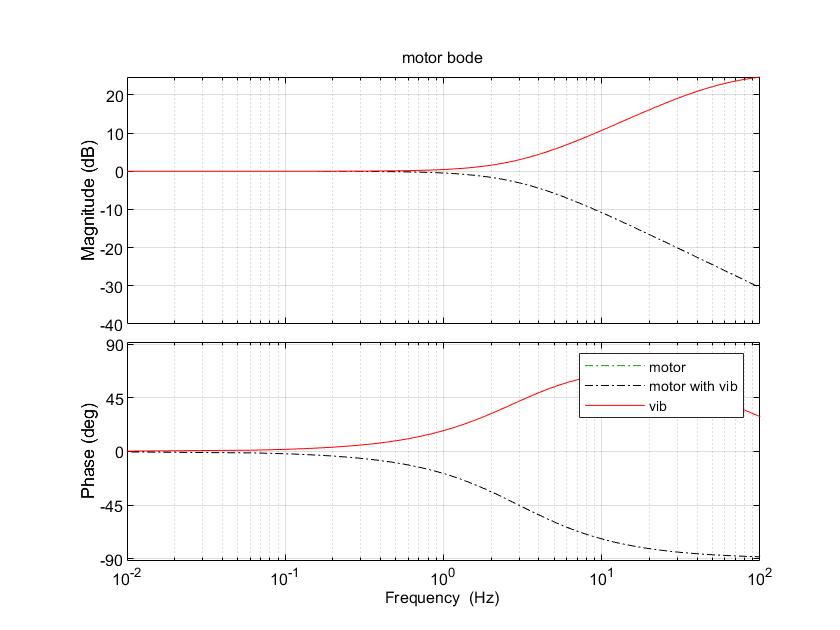

% -------------------------------------------------------
% 构造电机的传递函数，惯性环节，1/(Ts+1)，T=1/(2*pi*fc)
% mot_fc_Hz = 3Hz，表征着电机传递函数的截止频率，单位是Hz
% 截止频率从Hz转换成rad/s
% 计算出一阶惯性环节，表征电机的传递函数
% 疑问1（未解决）：电机传递函数的输入量和输出量分别是什么？
% 推测：输入量是PWM波的电压平均值，输出量是电机的转速
motor_tf = tf(1,[1/(2*pi*mot_fc_Hz) 1]);

% The change of motor bandwidth will hardly cause the change of resonance peak
% 问题2（未解决）：配置频率为20Hz。这个意义是什么？
f_cfg = 20;
% 问题3：把电机的截止频率赋值给了f_bs，这有什么意义？
f_bs = mot_fc_Hz;
% 用电机的截止频率与配置频率构造了电机振动的传递函数
% 振动1的电机传递函数
% 问题：振动1的电机传递函数这么构造有什么意义呢？
mot_vib1 = tf([1/(2*pi*f_bs) 1],[1/(2*pi*f_bs*f_cfg) 1]);
% 振动2的电机传递函数
mot_vib2 = tf([1/(2*pi*1) 1],[1/(2*pi*1) 1/2]);
% 问题4（已解决）：这个变量有什么意义？把频率7Hz转换成了角频率，这又有什么意义？
% 回答：f_reso1代表系统的固有频率，也就是共振频率。二阶传递函数中的频率
% 用的是角频率，所以在这里把共振频率从Hz转换到了rad/s。
f_reso1 = 7*2*pi;
% 问题5（已解决）：这个变量有什么意义？
% 回答：xi_reso1是阻尼比。它配合固有/共振频率，可以计算得到二阶
% 传递函数的系数。
xi_reso1 = 0.3;
% 参考p81的公式3-11，用二阶传递函数来构造电机的共振传递函数
% 分子的构造：0.8*固有频率的平方。
% 问题6（未解决）：为何这里有系数0.8？
% 回答：
% 分母的构造：很标准的二阶系统的分母构造。
mot_vibReso = tf(0.8*f_reso1^2,[1 2*xi_reso1*f_reso1 f_reso1^2]);

% Motor with vibration, which is the low frequency resonance point
% 问题7（未解决）：这里把电机的传递函数赋给了带有振动的电机传递函数。这是个没有任何修改的直接赋值，这是为什么呢？
motor_with_vib_tf = motor_tf;

% 问题8（未解决）：电机的传递函数motor_tf和带有振动的电机传递函数motor_with_vib_tf是相同的，画在bode图中有什么意义呢？
% mot_vib1的构造思路是什么？它里面加入了一个额外配置的极点，这是在加入控制器来调节它吗？
figure
bode(motor_tf,opt,'g-.');
hold on
bode(motor_with_vib_tf,opt,'k-.');
bode(mot_vib1,opt,'r-');
legend("motor",'motor with vib','vib');
title("motor bode")

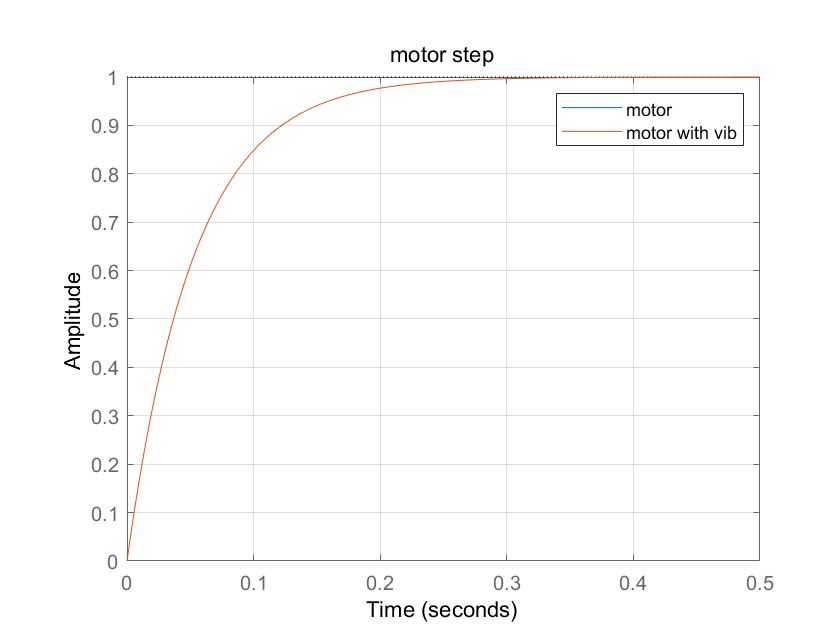

% 下面这个图应该是只用画一根线就OK的，因为电机传递函数motor_tf和带有振动的电机传递函数motor_with_vib_tf是相同的。
figure
step(motor_tf);
hold on
step(motor_with_vib_tf);
grid;
legend("motor","motor with vib")
title("motor step")

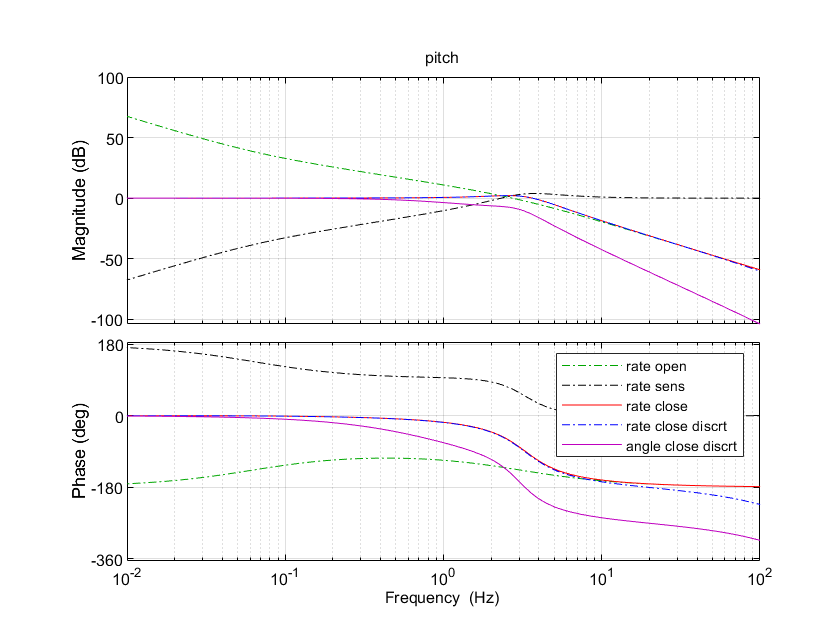



% -------------------------------------------------------
% % pitch channel
% % modify control
% 从注释来看，这里是在设计俯仰通道的控制器
% 横滚和俯仰通道的控制器增益设计为100
% 问题：为什么要把增益定为100？
ctrl_gain_rp = 100;
% 设计了个俯仰角速率的PI控制器
% 问题：参数这么设计的原因是什么？
pitch_rate_ctrl_tf=tf(pid(0.2,0.08, 0.00)*ctrl_gain_rp);
% 设计了个俯仰角的P控制器
% 问题（未解决）：为什么这么设计？
% 回答：
pitch_angle_ctrl_tf = tf(pid(4, 0, 0));

% 问题（未解决）：这个变量的作用是什么？
% 回答：
filt_butt2_fc20s = 1;
% 问题（未解决）：这个变量的作用是什么？
% 回答：
bsf = 1;
% 原始模型：控制器输入为角度deg偏差，电机模型的输入为转速，输出为转速，平方后乘以系数变成力，再乘以力臂变成扭矩
% 工作点线性化模型：控制器输入为角度deg偏差，计算后经过缩放映射，变成pwm到电机模型，电机模型输出pwm经过映射变成力
% pitch_rate_ctrl_tf是角速度环控制器
% servo_gain_rp=0.142857，控制器的servo_out rp出来后/7，
% 乘以0.707是sqrt(2)/2，为动力分配量，此时已经转换到了pwm。NOTE:如果PWM到RPM是线性映射，那么转速传递函数就是PWM传递函数。
% lift_pitch_per_pwm是pwm到力的映射
% 力乘以力臂arm_pitch_m为转矩，除以转动惯量Iyy，得到角加速度，单位为rad/s，*180/pi转换为deg/s
% 角加速度积分得到角度 问题：这里写错了吗？角加速度积分后得到的是角速度啊？
%                                 1         k
% omega_c---+---|PID|---gain---|------|---|---|---omega
%                                Ts+1       s
% 俯仰角通道：PWM高电平持续时间每变化1us对应的升力变化*俯仰通道力臂/转动惯量---->角加速度变化(rad/s^2)---->deg/s^2
beta_amp_pitch = lift_pitch_per_pwm * arm_pitch_m / Iyy * (180/pi);
% 俯仰角加速度积分---->俯仰角速度
% 传递函数，表征着PWM占空比发生1us变化---->俯仰角速度的变化
beta_tf_pitch  = beta_amp_pitch * tf(1,[1 0]);

% 角速度开环bode, rate open
% 俯仰角速度回路的开环传递函数的构造过程如下：
pitch_rate_open_tf  = pitch_rate_ctrl_tf * servo_gain_rp * mot_alloc_rp * motor_with_vib_tf * beta_tf_pitch;

% 俯仰角速率控制器*横滚俯仰通道增益*横滚和俯仰通道控制分配系数*带振动的电机传递函数*俯仰角速度传递函数（PWM高电平持续时间变化---->俯仰角速度变化）
% 传递函数的输入是俯仰角的误差theta_d
% * pitch_rate_ctrl_tf对应：控制器的输出---->电机转速（期望）
% * mot_alloc_rp * motor_with_vib_tf对应：期望的电机转速---->电机转速的响应（实际，且经过了控制分配）
% * beta_tf_pitch对应：PWM占空比发生1us变化---->俯仰角速度的变化
% * servo_gain_rp * beta_tf_pitch对应：每1rad/s或1RPM的转速变化---->俯仰角速度的变化

% pitch_rate_ctrl_tf * servo_gain_rp * mot_alloc_rp对应着期望转速
% motor_with_vib_tf对应着期望转速过电机传递函数后的实际转速
% pitch_rate_open_tf  = pitch_rate_ctrl_tf * mot_alloc_rp * motor_with_vib_tf * servo_gain_rp * beta_tf_pitch;

% 角速度开环灵敏度, rate sens
% 问题9（未解决）：灵敏度函数怎么算？直接取倒数？
% 回答：
pitch_rate_sens_tf = 1/(1+pitch_rate_open_tf);

% 角速度带滤波器闭环，rate close
% 角速度控制闭环
pitch_rate_closed_tf = feedback(pitch_rate_open_tf, 1);%filt_butt2_fc20*bsf

% 角度控制闭环
pitch_angle_closed_tf = feedback(pitch_rate_closed_tf*tf(1,[1 0])*pitch_angle_ctrl_tf, 1);

% 画图呈现
figure;
bode(pitch_rate_open_tf,opt,'g-.');
hold on;
bode(pitch_rate_sens_tf,opt,'k-.');
bode(pitch_rate_closed_tf,opt,'r-');
% 角速度带滤波器闭环离散化，
bode(c2d(pitch_rate_closed_tf,deltaT),opt,'b-.');
bode(c2d(pitch_angle_closed_tf,deltaT),opt,'m-');
legend('rate open','rate sens','rate close','rate close discrt','angle close discrt');
title('pitch');

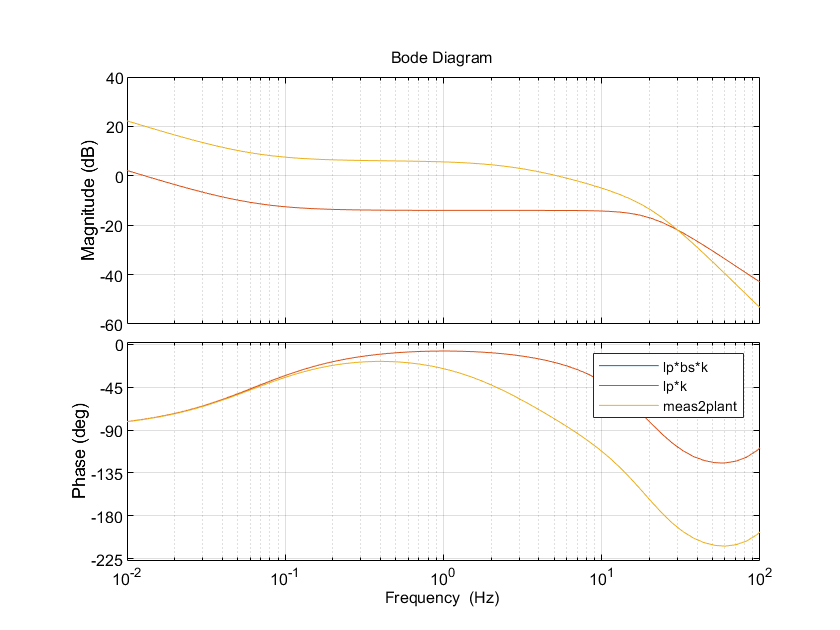


figure;
% 控制器的bode图
bode(filt_butt2_fc20*bsf*pitch_rate_ctrl_tf/ctrl_gain_rp,opt);hold on;
bode(filt_butt2_fc20*pitch_rate_ctrl_tf/ctrl_gain_rp,opt);
bode(filt_butt2_fc20*bsf*pitch_rate_ctrl_tf*servo_gain_rp*mot_alloc_rp*motor_with_vib_tf,opt);
legend('lp*bs*k','lp*k','meas2plant')

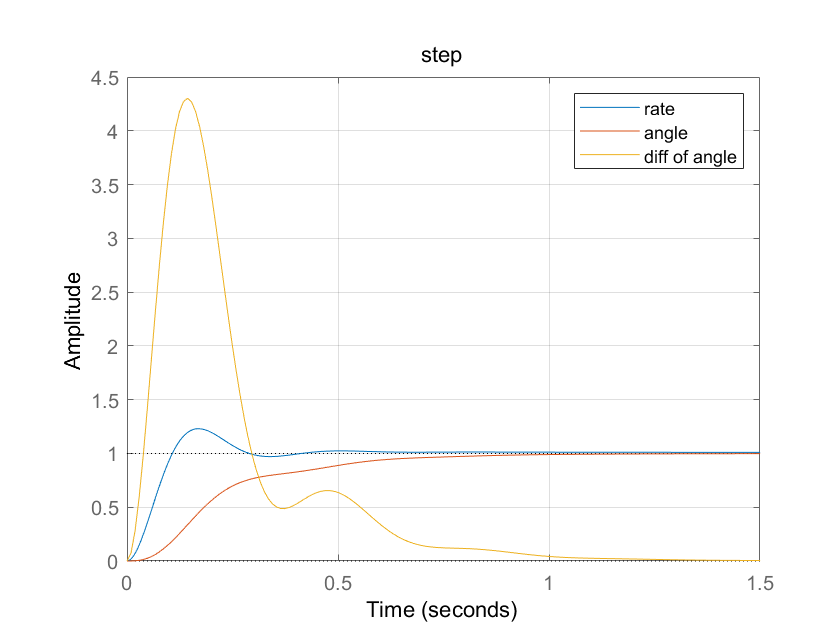

% 问题10（未解决）：为啥角度闭环控制回路还要微分一次？
% 回答：
figure;
step(pitch_rate_closed_tf);hold on;grid;
step(pitch_angle_closed_tf);
step(pitch_angle_closed_tf*tf('s'));
legend('rate','angle','diff of angle');
title('step')

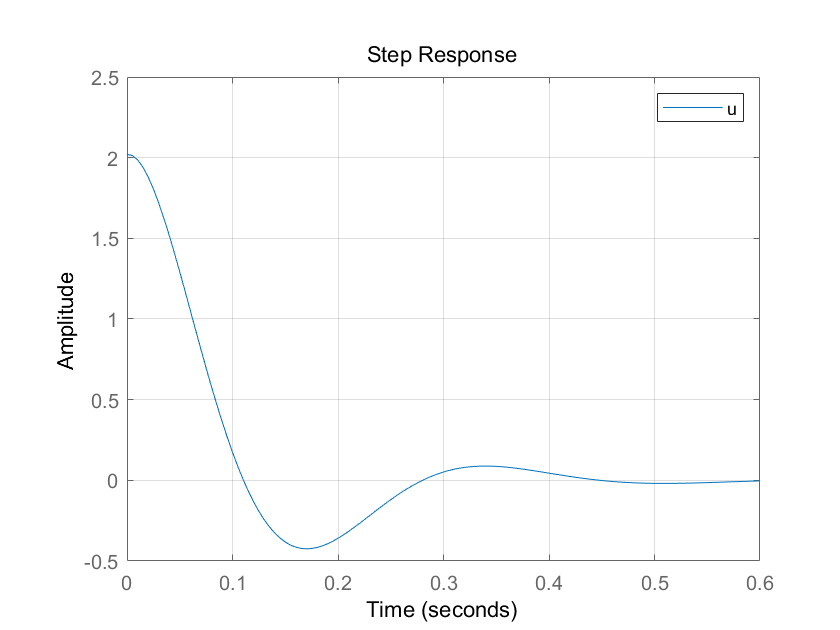

% 问题11（未解决）：没看懂这里是在计算什么？
% 回答：
figure;
step(pitch_rate_ctrl_tf*pitch_rate_sens_tf*servo_gain_rp*mot_alloc_rp);grid;
legend('u');

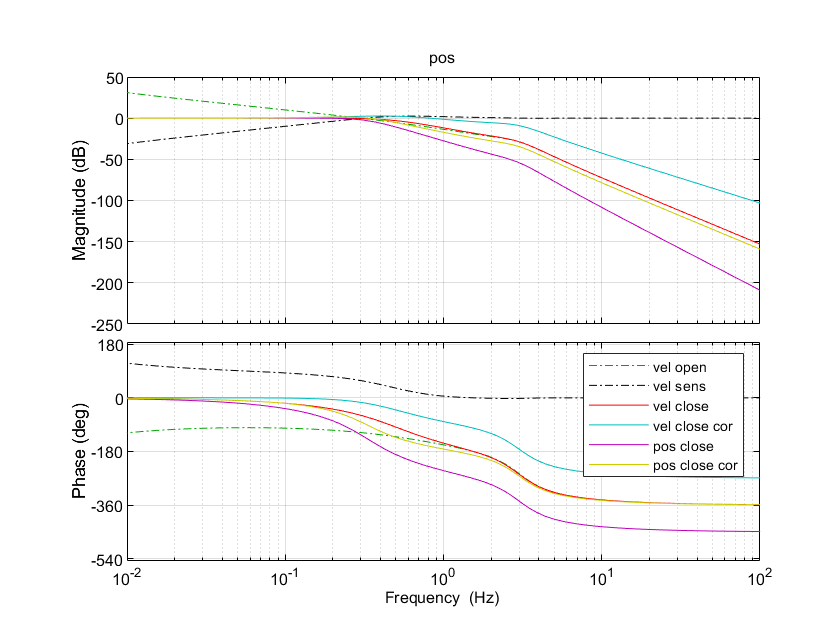

% -------------------------------------------------------
% % velocity and position
% 速度回路的截止频率0.01Hz
% 问题12（未解决）：这个截止频率在回路中对应什么？另外，这个截止频率太低了，它的真实意义是什么？
fc_vel = 0.01; %@Hz
vel_kp = 2.0;
vel_ki = 2 * pi *fc_vel;
theta_tf = pitch_angle_closed_tf;
% limit attitude angle in [-10, 10], @degree
acc_tf = theta_tf * (pi/180) * G_mss;
vel_ctrl_ff = .0*tf('s');
% vel loop use loop shaping controller
vel_ctrl_tf = tf(pid(vel_kp,vel_ki,0)) + vel_ctrl_ff;
vel_open_tf = vel_ctrl_tf / G_mss * (180/pi) * acc_tf * tf(1,[1 0]);
vel_sens_tf = 1/(1+vel_open_tf);

% vel loop vs add a diff seg（为了模拟飞机实际响应的特征）
vel_closed_tf = feedback(vel_open_tf,1);
vel_closed_tf_cor = feedback(vel_open_tf,1) * (1 + .6*tf('s')/1.2);
% pos loop control gain 1
pos_ctrl_tf = 1.;
pos_closed_tf = feedback(pos_ctrl_tf*vel_closed_tf*tf(1,[1 0]),1);
pos_closed_tf_cor = feedback(pos_ctrl_tf*vel_closed_tf*tf(1,[1 0]),1) * (1+.5*tf('s'));
% obverse attitude angle and pwm output

figure;
bode(vel_open_tf,opt,'g-.');
hold on;
bode(vel_sens_tf, opt, 'k-.');
bode(vel_closed_tf, opt, 'r-');
bode(vel_closed_tf_cor, opt, 'c-');
bode(pos_closed_tf, opt, 'm-');
bode(pos_closed_tf_cor, opt, 'y-');
legend('vel open','vel sens','vel close','vel close cor','pos close','pos close cor');
title('pos');

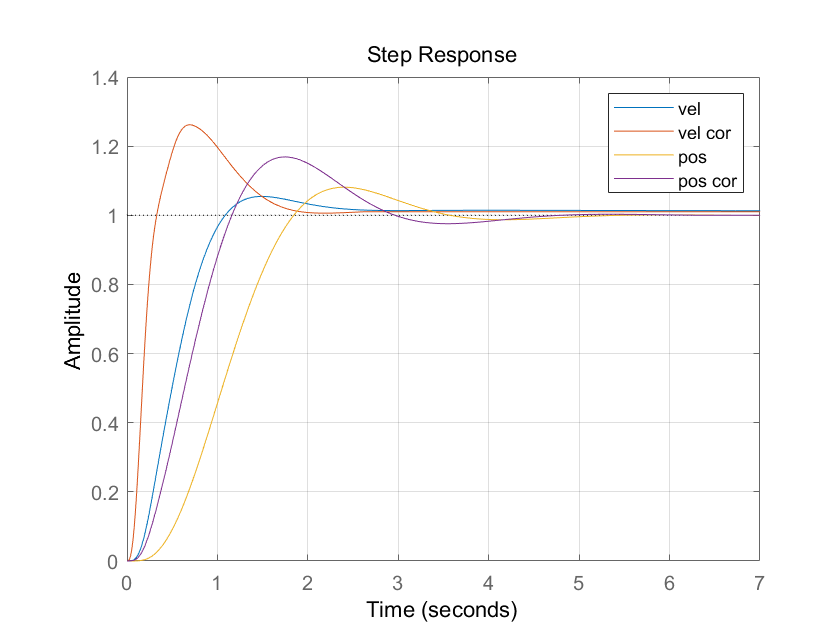


figure;
step(vel_closed_tf);grid;hold on;
step(vel_closed_tf_cor);
step(pos_closed_tf);%step(vel_ctrl_tf/(1+vel_open_tf));
step(pos_closed_tf_cor);
legend('vel','vel cor','pos','pos cor');

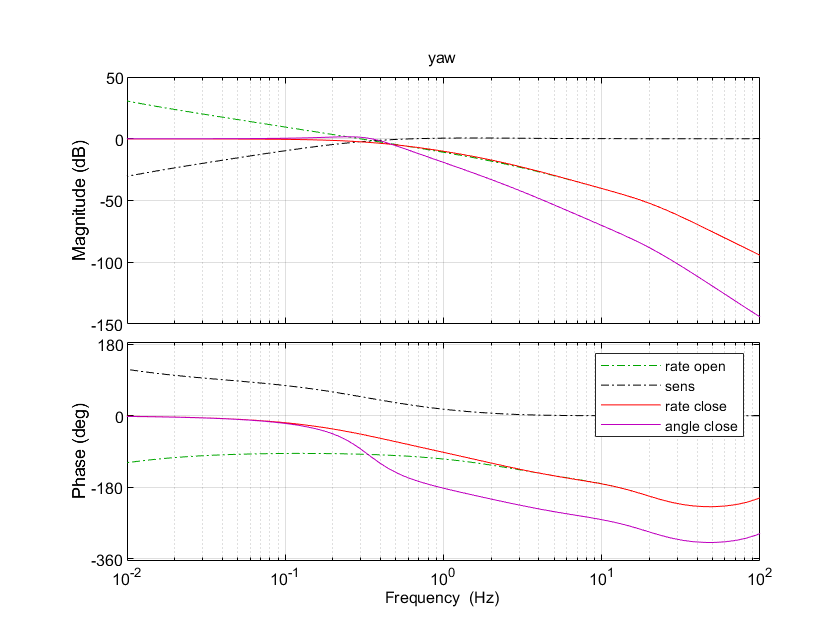


% ------
%% roll
% beta_amp_roll = arm_roll_m*lift_roll_per_pwm/Ixx * (180/pi);
% beta_tf_roll  = beta_amp_roll * tf(1,[1 0]);
% pitch_rate_open_tf  = ctrlR_tf * servo_gain_rp * filt_butt2_fc20 * motor_with_vib_tf * beta_tf_roll;
% 
% figure;
% opt=bodeoptions;
% opt.FreqUnits = 'Hz';
% opt.Grid = 'on';
% bode(pitch_rate_open_tf,opt,'g-.');
% grid;hold on;
% bode(feedback(pitch_rate_open_tf, filt_butt2_fc50),opt,'r-');
% bode(feedback(feedback(pitch_rate_open_tf,1)*tf(1,[1 0])*5,1),opt,'m-');
% legend('omega open','omega close','angle close');
% title('roll');

% -------------------------------------------------
% %Yaw control
% 偏航角控制
% 偏航角控制增益设为100
% 问题13（未解决）：为什么增益设置成100？
ctrlY_gain = 100;
% 问题14（未解决）：变量cor_y的含义和作用是什么？
cor_y = 1;
% 控制器的开环传递函数如下，并且观察到它是个PI控制器
ctrlY_tf = tf(pid(0.3,0.01,0)*ctrlY_gain) * cor_y;
% 问题14（未解决）：伺服增益为什么定为0.1？
servo_gain_y = 1/10;

% 扭矩
% 每个PWM的微秒变化，带来的角加速度变化（从"rad/s"转化成了"度/秒"）
beta_amp_yaw_mot = mot_torque_Nm_per_pwm / Izz * (180/pi);
% 安装角度偏差带来的扭矩
beta_amp_yaw_mount = mount_torque_Nm_per_pwm / Izz * (180/pi);
% tf(1,[1 0])是一个积分环节
% PWM一个微秒的变化带来的角加速度变化 + 安装角度引起的角加速度变化 --> 积分得到角速度变化
beta_tf_yaw = (beta_amp_yaw_mot + beta_amp_yaw_mount*motor_with_vib_tf)* tf(1,[1 0]);
% 偏航角速度的开环传递函数
yaw_rate_open_tf = ctrlY_tf * servo_gain_y * filt_butt2_fc20 * beta_tf_yaw;
% 偏航角速度的闭环传递函数
yaw_rate_close_tf = feedback(yaw_rate_open_tf, filt_butt2_fc10);

ctrlYawAngle = 2;
yaw_angle_close_tf = feedback(yaw_rate_close_tf*tf(1,[1 0])*ctrlYawAngle, 1);

figure;
opt=bodeoptions;
opt.FreqUnits = 'Hz';
opt.Grid = 'on';
opt.XLim = [0.01 100];

bode(yaw_rate_open_tf, opt, 'g-.');
hold on;
bode(1/(1+yaw_rate_open_tf),opt,'k-.');
bode(yaw_rate_close_tf, opt, 'r-');
bode(yaw_angle_close_tf, opt, 'm-');
legend('rate open','sens','rate close','angle close');
title('yaw');

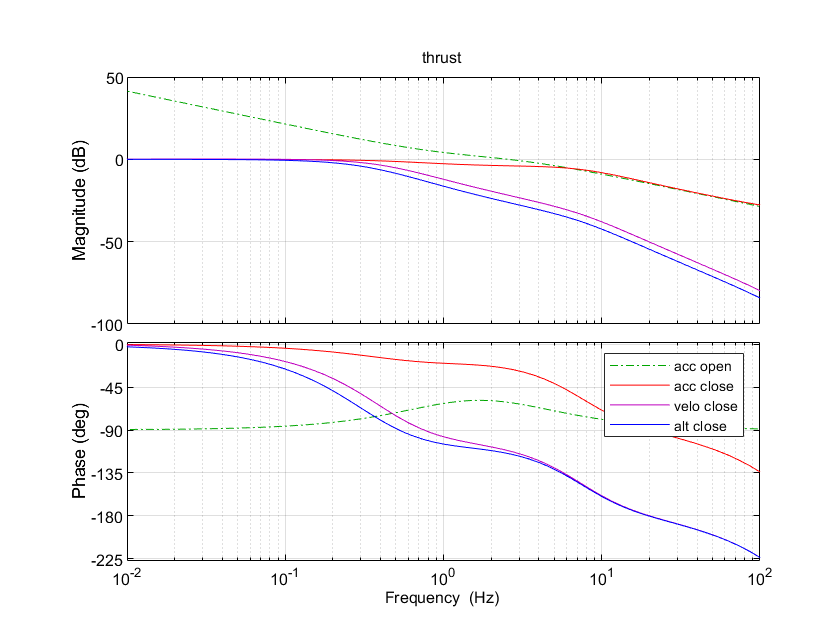

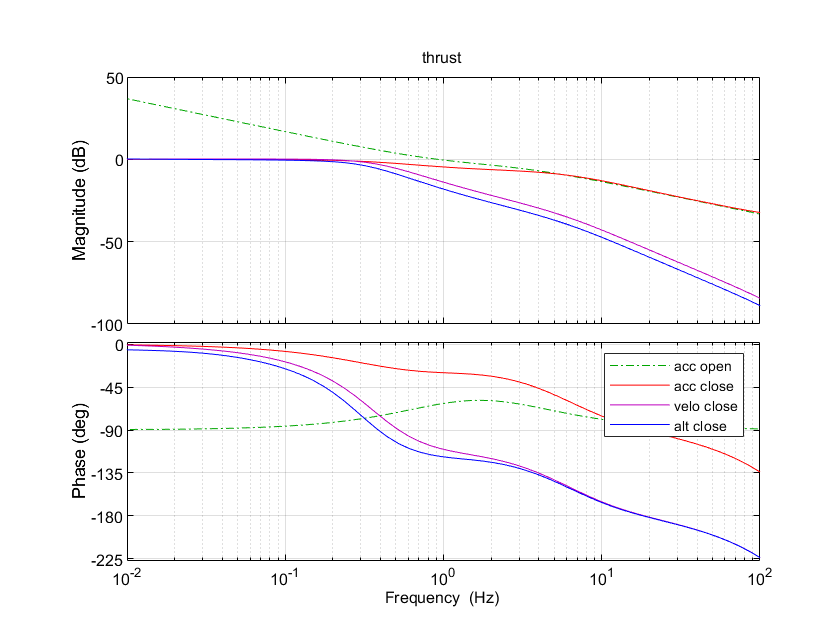

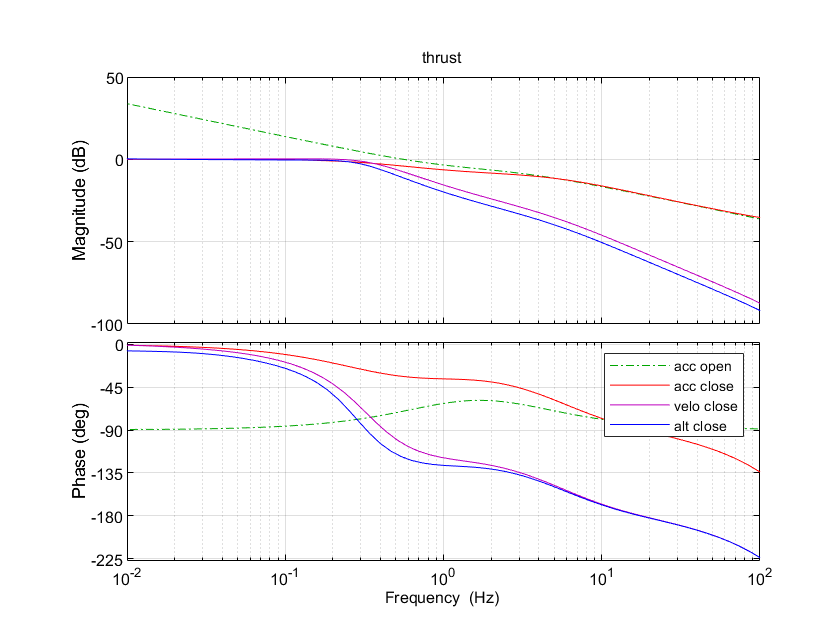


% -------------------------------------------------------
%% thrust
% 高度通道

% close all;

% mot_fc_Hz = .8;
% motor_tf = tf(1,[1/(2*pi*mot_fc_Hz) 1]);
% motor_thrust_amp = 52*9.806/775;

% 飞机空载、半载、满载3种工况下的模型
% 50kg 85kg 120kg
for weight = 50 : 35 : 120

    % 变量mot_lift_N_per_pwm对应着，每1us（微秒）的PWM高电平持续时间对应的旋翼升力和扭矩的改变量
    % 4个电机合力引起的高度通道的加速度变化
    accel_amp_thrust = mot_lift_N_per_pwm * 4 /weight;

    % 高度通道控制增益设置为100
    ctrl_gain_t = 100;
    % 加速度控制的传递函数如下
    accel_ctrl_tf = tf(pid(.2, 1.2, 0)) * ctrl_gain_t;
    
    % 带振动的加速度控制的开环传递函数如下
    accel_open_tf = accel_ctrl_tf * motor_with_vib_tf * accel_amp_thrust;

    filt_butt2_fc10 = d2c(tf(0.00554271721*[1 2 1],[1 -1.778632 0.8], deltaT));
    filt_butt2_fc30 = d2c(tf(0.04*[1 2 1],[1 -1.34897 0.514], deltaT));
    filt_butt2_fc5f = d2c(tf(0.0378*[1 1],[1 -0.92439], deltaT));
    filt_butt2_fc10f = d2c(tf(0.0729597*[1 1],[1 -0.8541], deltaT));
    fltp3 = d2c(tf(0.0230 *[1 1],[1 -0.953952555907763288800538248324301093817], deltaT));

%     accel_open_tf = accel_open_tf * tf(pid(1,1/(2*pi*.3),0));

    % filter@10Hz better
    % 带振动环节的加速度的闭环控制
    accel_close_tf = feedback(accel_open_tf, filt_butt2_fc10f);

    % velo_ctrl_tf = tf(pid(2.5,.5,0));
    % velo_ctrl_tf = tf(pid(5,.5,0))+tf('s');
    % 速度控制器传递函数如下
    velo_ctrl_tf = tf(pid(2.,0.1,0));
    % 垂向速度的闭环控制器的传递函数如下
    % 加速度闭环控制器的传递函数 * 积分环节 * 速度控制器的传递函数 ----> 速度控制器的闭环传递函数
    vel_vert_close_tf = feedback(accel_close_tf*tf(1,[1 0])*velo_ctrl_tf, 1);
    
    % 高度控制器设计成增益为0.5的比例增益环节
    alt_ctrl_tf = .5;
    % 高度控制器的闭环传递函数 = 
    % (速度闭环传递函数 * 积分环节 * 高度开环控制器的传递函数) * (1+0.6s/高度控制器)
    % ---->闭环反馈，反馈回路增益为1
    alt_close_tf = feedback(vel_vert_close_tf*tf(1,[1 0])*alt_ctrl_tf, 1) * (1+.6*tf('s')/alt_ctrl_tf); % overshoot

    figure;
    opt=bodeoptions;
    opt.FreqUnits = 'Hz';
    opt.Grid = 'on';
    opt.Xlim = [0.01 100];

    bode(accel_open_tf, opt, 'g-.');
    hold on;
    bode(c2d(accel_close_tf,deltaT), opt, 'r-');
    bode(c2d(vel_vert_close_tf,deltaT), opt, 'm-');
    bode(c2d(alt_close_tf,deltaT), opt, 'b-');
    legend('acc open','acc close','velo close','alt close');
    title('thrust');

%     figure;
%     step(accel_close_tf);grid;hold;step(vel_vert_close_tf);step(alt_close_tf);legend('acc','spd','alt');
    
%     figure;
%     bodemag(accel_open_tf*filt_butt2_fc10f,accel_open_tf*filt_butt2_fc5f,opt);
%     legend('10','3');
end